Tutorial03 Assignment

2.4 Plotting Trajectories

**2.3 Wandering on a Plane - Generating Trajectories**

Now: Want to create a rand walk of 500 steps.

=> Our trajectory will be a list of 500 x values and 500 y values.

Note: It's a good practice to let MATLAB know the length of the lists, bc it saves computation time.

walklength = 500;
x = zeros(1, walklength); y = zeros(1, walklength)

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


eqn1 shows that we can consider x and y separately.

% Creating two lists of 500 random binary digits
rlistx = rand(1, walklength);
rlisty = rand(1, walklength);
stepx = (rlistx>0.5);
stepy = (rlisty>0.5);
sum(stepx);
sum(stepx);

rlistx2 = rand(1, walklength);
rlisty2 = rand(1, walklength);
stepx2 = (rlistx2>0.5);
stepy2 = (rlisty2>0.5);
sum(stepx2);
sum(stepx2);

rlistx3 = rand(1, walklength);
rlisty3 = rand(1, walklength);
stepx3 = (rlistx3>0.5);
stepy3 = (rlisty3>0.5);
sum(stepx3);
sum(stepx3);

Now, convert the lists of steps into actual successive positions of the random walker.

a)  b)

Make three random walk trajectories.

% help cumsum
stepx = cumsum(-1+2*stepx)

stepx =      1     0    -1    -2    -3    -4    -3    -2    -1    -2    -1    -2    -1    -2    -3    -2    -1     0    -1     0    -1     0     1     2     1     2     3     4     3     2     1     2     3     2     3     2     3     4     3     4     5     4     3     2     3     2     3     2     3     2


stepy = cumsum(-1+2*stepy)

stepy =     -1    -2    -1     0     1     2     3     2     1     0    -1    -2    -1    -2    -1    -2    -1     0    -1    -2    -1    -2    -1    -2    -3    -4    -3    -4    -3    -2    -1     0     1     2     3     2     3     2     3     2     3     2     1     2     1     2     3     4     5     6



stepx2 = cumsum(-1+2*stepx2)

stepx2 =     -1    -2    -3    -2    -1    -2    -1    -2    -3    -2    -3    -4    -3    -2    -1    -2    -3    -4    -3    -2    -3    -2    -1     0    -1     0    -1     0     1     2     3     4     3     2     1     2     1     0     1     0    -1     0    -1    -2    -1    -2    -3    -2    -3    -4


stepy2 = cumsum(-1+2*stepy2)

stepy2 =     -1     0    -1    -2    -3    -2    -3    -2    -1    -2    -3    -2    -1    -2    -3    -4    -5    -6    -7    -8    -7    -6    -5    -4    -5    -6    -5    -6    -5    -6    -7    -8    -9   -10   -11   -12   -11   -10    -9   -10    -9    -8    -9   -10    -9   -10   -11   -10   -11   -12



stepx3 = cumsum(-1+2*stepx3)

stepx3 =      1     0    -1    -2    -1    -2    -3    -4    -3    -2    -3    -2    -1    -2    -3    -4    -5    -4    -3    -2    -3    -2    -3    -4    -5    -6    -5    -6    -7    -6    -7    -8    -9    -8    -9    -8    -9   -10   -11   -12   -13   -14   -13   -14   -15   -16   -17   -18   -19   -20


stepy3 = cumsum(-1+2*stepy3)

stepy3 =     -1    -2    -1    -2    -1    -2    -1    -2    -3    -4    -3    -4    -5    -6    -5    -6    -5    -6    -7    -6    -7    -8    -7    -8    -7    -6    -5    -6    -5    -4    -3    -2    -3    -2    -3    -4    -3    -2    -1     0    -1    -2    -1    -2    -1     0     1     2     3     2


Plot 3 side by side.

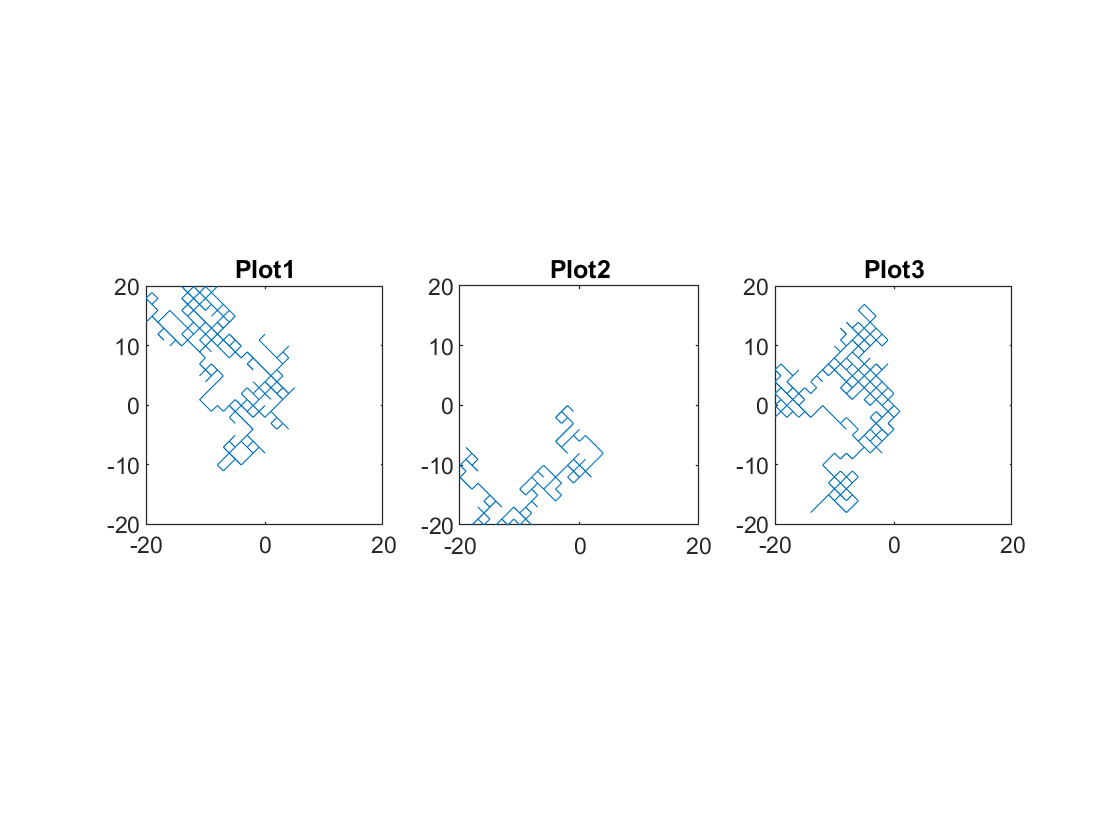

figure;
subplot(1,3,1)
plot(stepx, stepy)
axis equal
xlim([-20 20])
ylim([-20 20])
title('Plot1')

subplot(1,3,2)
plot(stepx2, stepy2)
axis equal
xlim([-20 20])
ylim([-20 20])
title('Plot2')

subplot(1,3,3)
plot(stepx3, stepy3)
axis equal
xlim([-20 20])
ylim([-20 20])
title('Plot3')

2.5 Plotting the 2D Random Walk Distribution

walklength = 1000;

for i = 1:600
    rlistx = rand(1, walklength);
    rlisty = rand(1, walklength);
    stepx = (rlistx>0.5);
    stepy = (rlisty>0.5);
    sum(stepx); sum(stepx);
    stepx = cumsum(-1+2*stepx);
    stepy = cumsum(-1+2*stepy);
    
    xfinal(i) = stepx(500); yfinal(i) = stepy(500);
    D(i) = stepx(500)^2 + stepy(500)^2;
    
end

xfinal

xfinal =     16   -22   -10    14     0     2   -12    42    36   -12   -26    18   -10    30   -14   -16   -24     0   -12    24   -20     4    18     6   -22   -26    10   -18    -6   -24    22    -2    46    34    -4   -32    18    -4   -46     8    14     6    14   -20   -18    -2    46    46   -18    -4


yfinal

yfinal =    -10    34    32     6    14   -12     6   -14     0   -36     0     2   -38   -56    18     0    24   -32   -22   -32   -28     4    10   -14   -42   -24   -20   -30   -12   -20    30    -4   -32     6    -2   -20   -16   -14   -26   -30    -2   -26   -38    14    36    34    30    -2    12   -26


D

D =          356        1640        1124         232         196         148         180        1960        1296        1440         676         328        1544        4036         520         256        1152        1024         628        1600        1184          32         424         232        2248        1252         500        1224         180         976        1384          20        3140        1192          20        1424         580         212        2792         964         200         712        1640         596        1620        1160        3016        2120         468         692


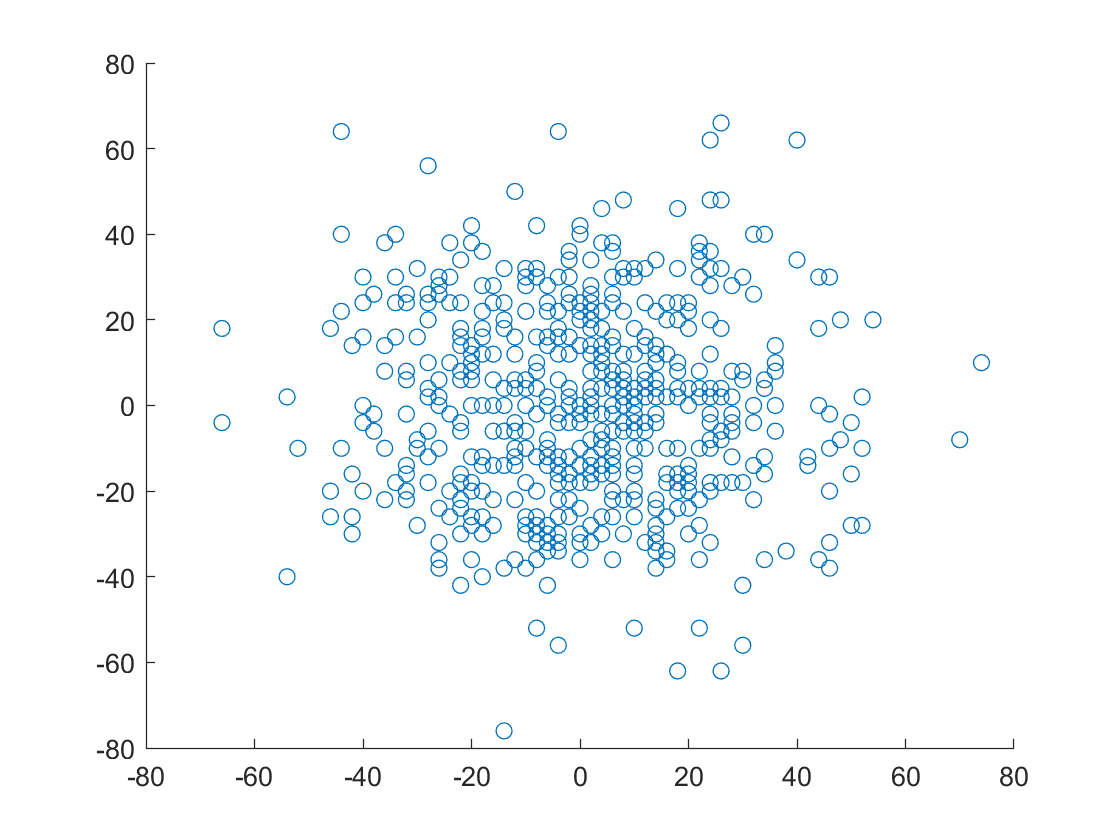


figure;
scatter(xfinal, yfinal)

b) Make histogram of all D values

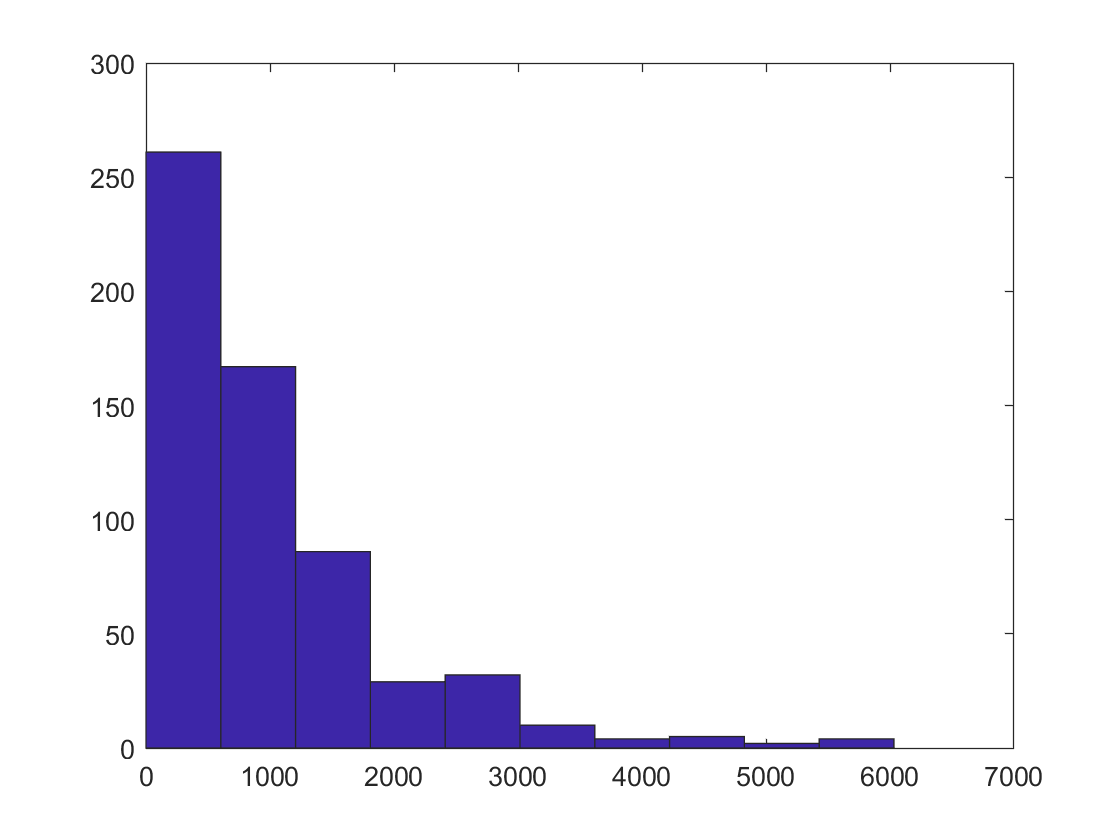

hist(D)

hist(D, 10)  % 10 bins

c) Use **mean** to find the "mean-square displacement" of the 500-step walk. 

d) Repeat to find the MSD of a 1000-step walk.

mean(D)  % Change walklength as appropriate

ans = 997.7067